% load animal data
clear

ExperimentFolder = "Pf_Lesion_Experiment_Oct_22";



% Set input folder

InputDirectory = "/media/sthitapati/Data/Behavioural_Data/matlab_output";


InputFolder = strcat(InputDirectory, "/", ExperimentFolder);

% display all animals in the input directory
GetDir = dir(InputFolder);

disp("Data for the following animals are in the input folder: ", newline)

Data for the following animals are in the input folder: 


for i = 3:numel(GetDir)
    disp(GetDir(i).name);
end

AllAnimals
SP100
SP102
SP77
SP78
SP80
SP81
SP82
SP83
SP84
SP85
SP86
SP87
SP89
SP90
SP92
SP93
SP94
SP95
SP96
SP97
SP98


% Load data
% Prerequisite: experiment must already curated (See
% bpod_data_curation_2afc Group)

if ~ any(strcmp('AllAnimals', {GetDir.name}))
    disp("Group data not curated")
end

data = strcat(InputFolder,'/AllAnimals/bpodTableAll.mat');
load(data)


% head(bpodTableAll)

% show trails of each animal in a tabular form

auditory = bpodTableAll(bpodTableAll.Protocol == "Auditory", :);
unique_id = unique(auditory.AnimalID);

disp("AUDITORY TRIALS:")

AUDITORY TRIALS:


for i = 1: length(unique_id)
    num_trials = numel(auditory.AnimalID(auditory.AnimalID == unique_id(i)));
    fprintf('%s : %d\n', unique_id(i), num_trials)
end

SP77 : 6507
SP78 : 7131
SP81 : 6964
SP82 : 7341
SP84 : 5864
SP87 : 6765
SP90 : 6096
SP92 : 5073
SP93 : 6795
SP96 : 7914
SP97 : 8045
SP100 : 8180
SP80 : 5160
SP83 : 6247
SP85 : 6905
SP86 : 5617
SP89 : 5259
SP94 : 5698
SP95 : 5089
SP98 : 5080
SP102 : 5039


% TODO: Define color scheme for each group

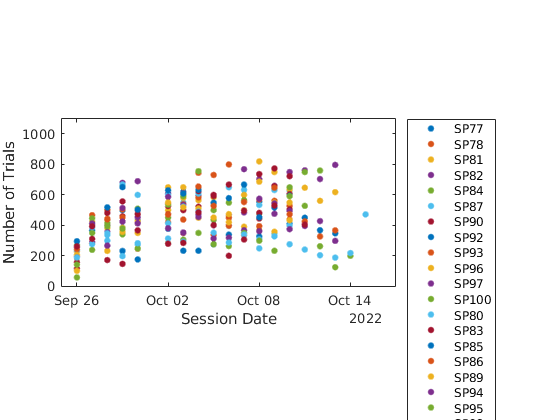

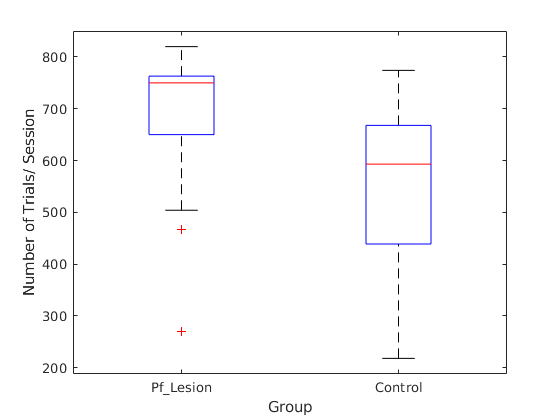

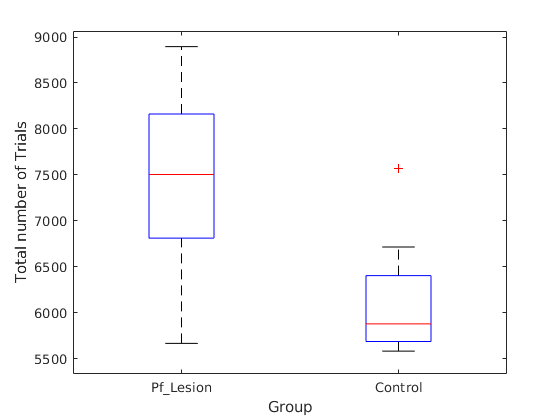

plotTrials(bpodTableAll);


% Plot trials vs performance: individual animals
animals = unique(bpodTableAll.AnimalID)

animals = 21×1 categorical array
     SP77 
     SP78 
     SP81 
     SP82 
     SP84 
     SP87 
     SP90 
     SP92 
     SP93 
     SP96 
     SP97 
     SP100 
     SP80 
     SP83 
     SP85 
     SP86 
     SP89 
     SP94 
     SP95 
     SP98 
     SP102 


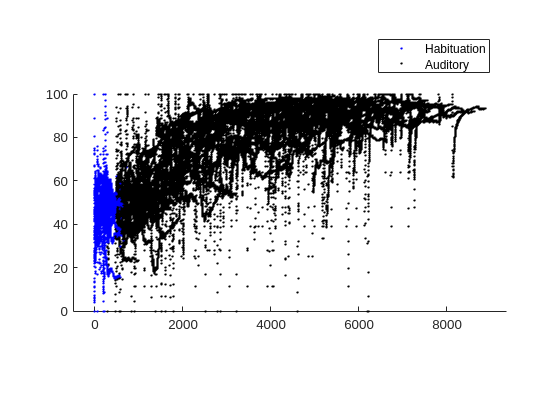


figure

hold on

for idx = 1: length(animals)

    % Find unique Protocols
    mouse_table = bpodTableAll(bpodTableAll.AnimalID == animals(idx), :);
    
    unique_protocols = mouse_table.Protocol;

    % x-axis: TrialIndex grouped according to Protocol
    trial_number = (1: length(mouse_table.TrialIndex))';
    % y-axis: Cumulative performance
    cumulative_performance = mouse_table.CumulativePerformance;
    % Smooth y data
    cumulative_performance = smoothdata(cumulative_performance, "SmoothingFactor", 0.01);
    % label and beutify the plot

    cum_performance_table = table(trial_number,cumulative_performance, unique_protocols);

    gscatter(cum_performance_table.trial_number, cum_performance_table.cumulative_performance, ...
    cum_performance_table.unique_protocols, "bk")
end
pbaspect([3 1.5 1])
hold off

% Plot trials vs performance: average/

% parecellate according to mice
% find out which max trials; zero-pad if necessary

a = 0;
for idx = 1: length(animals)
     m = bpodTableAll(bpodTableAll.AnimalID == animals(idx), :);
     disp(size(m));
end

        7018          29

        7619          29

        7504          29

        7887          29

        6161          29

        7402          29

        6605          29

        5666          29

        7505          29

        8438          29

        8628          29

        8896          29

        5731          29

        6715          29

        7567          29

        6212          29

        5878          29

        6300          29

        5581          29

        5657          29

        5695          29



cumPerAll = getCumPerAll(bpodTableAll);

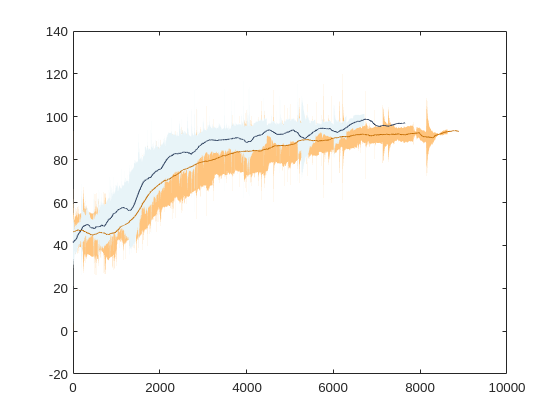

% use this container to specify colours
grp_uniq = unique(bpodTableAll.Group);


color_code = containers.Map;
% color_code("Casp") = '#223656';
% color_code("tdT") = '#C46C00';

color_code("Control") = '#223656';
color_code("Pf_Lesion") = '#C46C00';
% color_code("No_Surgery") = '#009900';

colorshade_code = containers.Map;
% colorshade_code("Casp") = '#e8f4f8';
% colorshade_code("tdT") = '#FFC47D';

colorshade_code("Control") = '#e8f4f8';
colorshade_code("Pf_Lesion") = '#FFC47D';
% colorshade_code("No_Surgery") = '#e8fbe8';

for k = 1: length(cumPerAll)
          
    cumPergroup = cumPerAll{k, 1};
    
    x = mean(cumPergroup, 2, "omitnan");
    x = smoothdata(x, "SmoothingFactor", 0.03);
    err = std(cumPergroup, 0, 2, "omitnan");
    err = smoothdata(err, "SmoothingFactor", 0.03);
    
    p = plot(x, "k", "LineStyle","-");
    
    p.Color = color_code(string(grp_uniq(k)));
    
    hold on
%     plot(x + err)
%     plot(x - err)
    
    ax = gca;
    
    x(isnan(x)) = 0;
    err(isnan(err)) = 0;
    
    trials = 1:length(x);
    
    x1 = [trials, fliplr(trials)];
    y1 = [(x -err)', fliplr((x + err)')];
    
    f = fill(ax, x1, y1, "g");
    f.EdgeColor = "none";
    f.FaceColor = colorshade_code(string(grp_uniq(k)));
    
    uistack(f, "bottom")
end


hold off

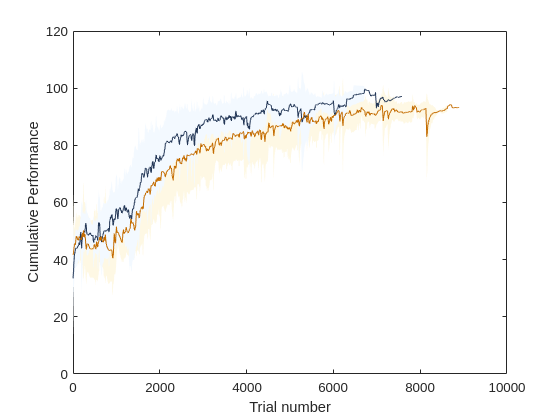

grp_uniq = unique(bpodTableAll.Group);
plotCumulativePerformance(cumPerAll, grp_uniq);

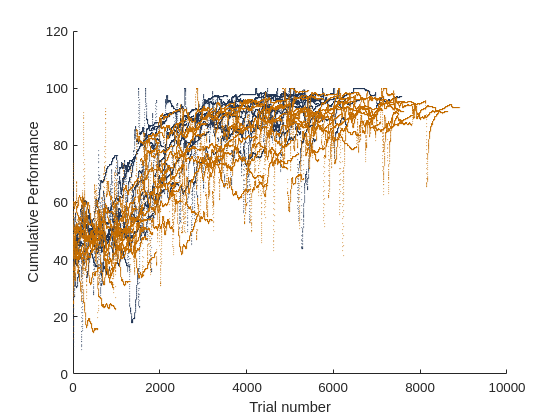



plotCumulativePerformance_all_mice(bpodTableAll);

% Plot visual

B = bpodTableAll(bpodTableAll.Protocol == "Visual", :);

plotTrials(B);

plotCumulativePerformance_all_mice(B);
title("Protocol: Visual")

CP = getCumPerAll(B);

plotCumulativePerformance(CP, grp_uniq)
title("Protocol: Visual")

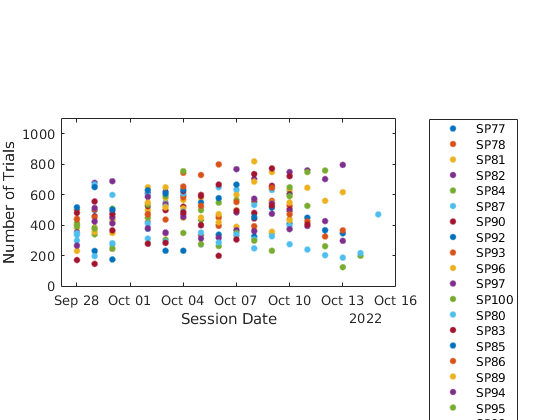

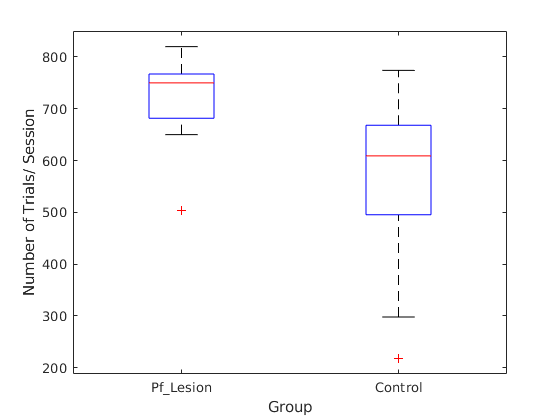

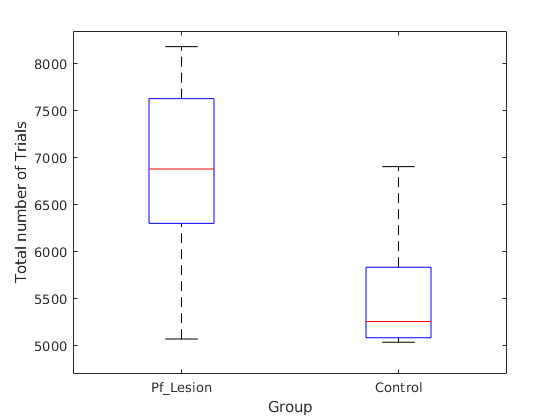

% Plot auditory

B = bpodTableAll(bpodTableAll.Protocol == "Auditory", :);

plotTrials(B);

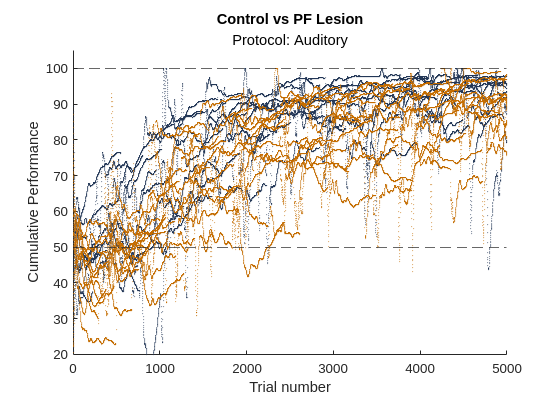


plotCumulativePerformance_all_mice(B);
xlim([0 5000]);
ylim([20 105]);
yline(100, "--");
yline(50, "--");
pbaspect([1 0.7 0.6])
title("Control vs PF Lesion","Protocol: Auditory")

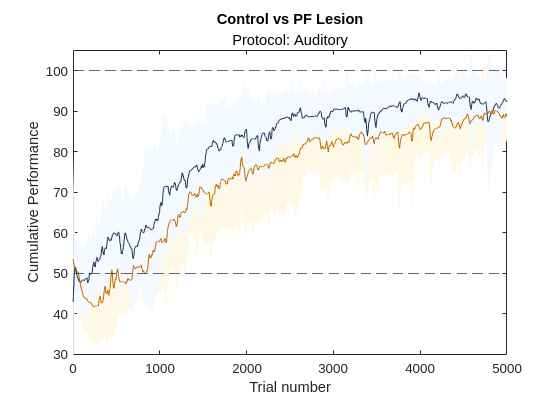


CP = getCumPerAll(B);

plotCumulativePerformance(CP, grp_uniq)
xlim([0 5000]);
ylim([30 105]);
yline(100, "--");
yline(50, "--");
pbaspect([1 0.7 0.6])
title("Control vs PF Lesion","Protocol: Auditory")

   % For Performance for Visual

B_vis = rowfun(@measurePerformance, bpodTableAll(bpodTableAll.Protocol == "Visual", :), "InputVariables", ["FirstPoke", "Contingency"], "GroupingVariables", ...
                ["TrialHighPerc","Group", "Contingency", "AnimalID", "SessionDate"] ...
                , "OutputVariableNames", ["RightCount", "Total", "PercentRight", "percentCorrect"]);

B_vis = B_vis(B_vis.TrialHighPerc == 2, :);
colors = ["#223656", "#C46C00"];

session_uniq = unique(B_vis.SessionDate);

t = tiledlayout('flow');

for k = 1: length(session_uniq)
    ax = nexttile;
    B2 = B_vis(B_vis.SessionDate == session_uniq(k), :);
    boxplot(ax, B2.percentCorrect, B2.Group, "ColorGroup", colors)
    ax = gca;
    ax.XDir = "reverse";
    ylim([0, 1.1])
    titl = title(string(session_uniq(k)));
    titl.FontSize = 8;
    titl.FontWeight = "bold";
    ylabel("Percent Correct", "FontSize", 8);
    pbaspect([1 1.1 1])

end    

t.Padding = "compact";
t.TileSpacing = "compact";
title(t,"Protocol: Visual");



% For Performance for Auditory

B_aud = rowfun(@measurePerformance, bpodTableAll(bpodTableAll.Protocol == "Auditory", :), "InputVariables", ["FirstPoke", "Contingency"], "GroupingVariables", ...
                ["TrialHighPerc","Group", "Contingency", "AnimalID", "SessionDate"] ...
                , "OutputVariableNames", ["RightCount", "Total", "PercentRight", "percentCorrect"]);

B_aud = B_aud(B_aud.TrialHighPerc == 2, :);
colors = ["#223656", "#C46C00"];

session_uniq = unique(B_aud.SessionDate);

t = tiledlayout('flow');

for k = 1: length(session_uniq)
    ax = nexttile;
    B2 = B_aud(B_aud.SessionDate == session_uniq(k), :);
    boxplot(ax, B2.percentCorrect, B2.Group, "ColorGroup", colors)
    ax = gca;
    ax.XDir = "reverse";
    ylim([0, 1.1])
    titl = title(string(session_uniq(k)));
    titl.FontSize = 8;
    titl.FontWeight = "bold";
    ylabel("Percent Correct", "FontSize", 8);
    pbaspect([1 1.1 1])

end    

t.Padding = "compact";
t.TileSpacing = "compact";
title(t,"Protocol: Auditory");
  


% Plot reaction time as per group
session_uniq = unique(bpodTableAll.SessionDate)

t = tiledlayout('flow')
for i = 1: length(session_uniq)
    B = bpodTableAll(bpodTableAll.SessionDate == session_uniq(i), :);
    grp_uniq = unique(B.Group);
    
    nexttile
    for k = 1: length(grp_uniq)
    
        histogram(B.TResponseTime(B.Group == grp_uniq(k), :), "BinWidth", 0.05, "FaceAlpha", 0.4)
        hold on
    end
    ttle = strcat(string(B.Protocol(i)), ": ", string(B.SessionDate(i)));
    title(ttle)
    xlabel("Reaction Time (in s)")
    ylabel("Count")
    xlim([0 4])
end

title(t, "17 mice of Pf Caspase Experiment")

## **Functions**

function [data_mean, data_std] = calculateSummary(data)
     data_mean = mean(data); 
     data_std = std(data, 0);
     
end


function [RightCount, Total, PercentRight, PercentCorrect] = measurePerformance(FirstPoke, Contingency)

FirstPoke(isnan(FirstPoke)) = 0;

RightCount = nnz(FirstPoke == 2);
Total = numel(FirstPoke);
PercentRight = RightCount ./ Total;

    if Contingency == 1
          
        PercentCorrect = RightCount ./ Total;
                
    elseif Contingency == -1
        
        PercentCorrect = 1 - (RightCount ./ Total);
        
    end
end


function plotTrials(bpodTableAll)
    
    T = rowfun(@max, bpodTableAll, "InputVariables", "TrialIndex", "GroupingVariables", ["AnimalID","SessionDate"] ...
               , "OutputVariableNames", "nTrial");
    
    figure();
    gscatter(T.SessionDate, T.nTrial, T.AnimalID)
    xlabel("Session Date")
    ylabel("Number of Trials")
    ylim([0 1100])
    lgd = legend;
    lgd.Location = "bestoutside";
    pbaspect([2 1 1])
    
    T2 = rowfun(@max, bpodTableAll, "InputVariables", "TrialIndex", "GroupingVariables", ["Group","SessionDate"] ...
    , "OutputVariableNames", "nTrial");

    figure();
    boxplot(T2.nTrial, T2.Group)
    axes = gca();
    xlabel("Group")
    ylabel("Number of Trials/ Session")
    axes.XDir = "reverse";
    
    
    T3 = rowfun(@max, bpodTableAll, "InputVariables","TrialIndex", "GroupingVariables",["Group", "AnimalID"], ...
    "OutputVariableNames","totalTrials");
    T3.Group = categorical(T3.Group);
    
    % Use this container as x-axis of all categorical summary plots when
    % overlaying plots
    
    c = containers.Map;
    
%     c("varS") = 1;
%     c("Casp") = 1;
%     c("tdT") = 2;
    c("Control") = '#223656';
    c("Pf_Lesion") = '#C46C00';
%     c("No_Surgery") = '#009900';
    
    figure();

    boxplot(T3.GroupCount, T3.Group)
    axes = gca();
    xlabel("Group");
    ylabel("Total number of Trials");
    axes.XDir = "reverse";
    
%     hold on
%     
%     for i = 1:numel(T3.Group)
%         idx = c(string(T3.Group(i)));
%         scatter(idx, T3.GroupCount(i))
%     end
%     
%     hold off
end


function cumPerAll = getCumPerAll(bpodTableAll)
    
    T3 = rowfun(@max, bpodTableAll, "InputVariables","TrialIndex", "GroupingVariables",["Group", "AnimalID"], ...
        "OutputVariableNames","totalTrials");
    T3.Group = categorical(T3.Group);
    
    % Accumulate trial number vs perfomrance array; note they are of unequal size 
    % Pad with NaNs
    % Make separate arrays for groups
    
    
    max_trial = max(T3.GroupCount);
    grp_uniq = unique(bpodTableAll.Group);
    
    cumPerAll = cell(length(grp_uniq), 1);
    
    
    for k = 1: length(grp_uniq)
    
        B = bpodTableAll(bpodTableAll.Group == grp_uniq(k), ["CumulativePerformance", "AnimalID"]);
        mouse_uniq = unique(B.AnimalID);
        
        cumPerAll{k, 1} = zeros(max_trial, length(mouse_uniq));
        
        for i = 1:length(mouse_uniq)
            cumPerMouse = bpodTableAll.CumulativePerformance(bpodTableAll.AnimalID == mouse_uniq(i));
            nans_to_pad = max_trial - length(cumPerMouse);
            if nans_to_pad == 0
                cumPerAll{k, 1}(:, i) = cumPerMouse;
            elseif nans_to_pad > 0
                cumPerMouse(end: end + nans_to_pad) = nan; 
                cumPerAll{k, 1}(:, i) = cumPerMouse;
            end
        end
    end

end

function plotCumulativePerformance(cumPerAll, grp_uniq)
    
    color_code = containers.Map;
%     color_code("varS") = '#223656';
%     color_code("Casp") = '#223656';
%     color_code("tdT") = '#C46C00';
    color_code("Control") = '#223656';
    color_code("Pf_Lesion") = '#C46C00';
%     color_code("No_Surgery") = '#009900';
    
    colorshade_code = containers.Map;
%     colorshade_code("varS") = '#e8f4f8';
%     colorshade_code("Casp") = '#e8f4f8';
%     colorshade_code("tdT") = '#FFC47D';

    colorshade_code("Control") = '#f3f9ff';
    colorshade_code("Pf_Lesion") = '#fef8e4';
%     colorshade_code("No_Surgery") = '#e8fbe8';
    
    for k = 1: length(cumPerAll)
              
        cumPergroup = cumPerAll{k, 1};
        
        x = mean(cumPergroup, 2, "omitnan");
        x = smoothdata(x, "movmean", 20);
        err = std(cumPergroup, 0, 2, "omitnan");
        err = smoothdata(err, "movmean", 20);
        
        p = plot(x, "k", "LineStyle","-");
        
        p.Color = color_code(string(grp_uniq(k)));
        
        
        xlabel("Trial number");
        ylabel("Cumulative Performance");
        
        
        hold on
    %     plot(x + err)
    %     plot(x - err)
        
        ax = gca;
        
        x(isnan(x)) = 0;
        err(isnan(err)) = 0;
        
        trials = 1:length(x);
        
        x1 = [trials, fliplr(trials)];
        y1 = [(x -err)', fliplr((x + err)')];
        
        f = fill(ax, x1, y1, "g");
        f.EdgeColor = "none";
        f.FaceColor = colorshade_code(string(grp_uniq(k)));
        
        uistack(f, "bottom")
    end
    
    
    hold off
end

% Plot cumulative performance across trials

function plotCumulativePerformance_all_mice(bpodTableAll)

    % use this container to specify colours

    color_code = containers.Map;
%     
%     color_code("Casp") = '#223656';
%     color_code("tdT") = '#C46C00';
%     color_code("varS") = '#223656';
    color_code("Control") = '#223656';
    color_code("Pf_Lesion") = '#C46C00';
%     color_code("No_Surgery") = '#009900';


    grp_uniq = unique(bpodTableAll.Group);
    
    for k = 1: length(grp_uniq)
        
        B = bpodTableAll(bpodTableAll.Group == grp_uniq(k), ["CumulativePerformance", "AnimalID"]);
        
        mouse_uniq = unique(B.AnimalID);
    
        
        for i = 1: numel(mouse_uniq)
        
    
            cumPer = bpodTableAll(bpodTableAll.AnimalID == mouse_uniq(i), "CumulativePerformance");
            smo = smoothdata(cumPer.CumulativePerformance, "movmean", 20);
            idx = 1:length(smo);
            p = scatter(idx, smo);
            ylim([0, 120])
            xlabel("Trial number");
            ylabel("Cumulative Performance");
            
            p.MarkerEdgeColor = "none";
            p.MarkerFaceColor = color_code(string(grp_uniq(k)));
            p.SizeData = 1;
            p.MarkerFaceAlpha = 0.5;
            hold on
        end
        
        
        % Plot mean of different groups
           
        
    end
    

    hold off
    
end